# In der Dokumentation verwendete Darstellungen für die Analyse der Streckensimulationen

% Angabe des Speicherortes und des simulierten Fahrzeugtypes
Speicherort = "Geschwindigkeitsoptimierte_Simulation"; % Fahrplanoptimierte_Simulation";
Fahrzeug = "RE450";

## 1.1)  Fahrtsimulation Beschleunigung/Geschwindigkeit einzeln (x-Achse = Fahrtzeit):

fnStr = fieldnames(SimStreckenU);

% Darstellung Geschwindigkeit und Beschleunigung jeder Strecke in
% Abhängigkeit der Fahrtzeit
for n = 1:numel(fnStr)
    figure;
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
    hold on
    yyaxis left
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Geschwindigkeit)
    ylabel('Geschwindigkeit [km/h]')
    yyaxis right
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Beschleunigung)
    ylabel('Beschleunigung [m/s^2]')
    xlabel('Fahrzeit')
    title('Geschwindigkeits- und Beschleunigungsverlauf der Fahrsimulation')
    %subtitle('Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    subtitle('Strecke: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' mit geschwindigkeitsoptimierter Sim.');
    grid()
    hold off
    % speichern der Grafiken als fig und als png
    savename = string(extractBefore(fnStr{n},'_')) + '_' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\Geschwindigkeit_Beschleunigung\', savename +'.png');
    exportgraphics(gcf, filename, 'Resolution',300)
   
end

## 1.2.) Fahrtsimulation Beschleunigung/Geschwindigkeit einzeln (x-Achse = Strecke):

fnStr = fieldnames(SimStreckenU);

% Darstellung Geschwindigkeit und Beschleunigung jeder Strecke in
% Abhängigkeit der Strecke
for n = 1:numel(fnStr)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
    hold on
    yyaxis left
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Geschwindigkeit)
    ylabel('Geschwindigkeit [km/h]')
    yyaxis right
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Beschleunigung)
    ylabel('Beschleunigung [m/s^2]')
    xlabel('Strecke [m]')
    title('Geschwindigkeits- und Beschleunigungsverlauf der Fahrtsimulation')
    %subtitle('Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    subtitle('Strecke: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' mit geschwindigkeitsoptimierter Sim.');
    grid()
    hold off
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\Geschwindigkeit_Beschleunigung\', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end


## 1.3.) Fahrtsimulation Leistung/Steigung einzeln (x-Achse = Fahrtzeit)

fnStr = fieldnames(SimStreckenU);

% Darstellung Geschwindigkeit und Beschleunigung jeder Strecke in
% Abhängigkeit der Fahrtzeit
for n = 1:numel(fnStr)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
    hold on
    yyaxis left
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Leistung/1000)
    ylabel('Leistung [MW]')
    yyaxis right
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Steigung)
    ylabel('Steigung [‰]')
    xlabel('Fahrzeit')
    title('Leistungsverlauf und Streckensteigung der Fahrtsimulation')
    %subtitle('Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    subtitle('Strecke: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' mit geschwindigkeitsoptimierter Sim.');
    grid()
    hold off
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\Leistung_Steigung\', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end


## 1.4.) Fahrtsimulation Leistung/Steigung einzeln (x-Achse = Strecke)

fnStr = fieldnames(SimStreckenU);

% Darstellung Geschwindigkeit und Beschleunigung jeder Strecke in
% Abhängigkeit der Strecke
for n = 1:numel(fnStr)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
    hold on
    yyaxis left
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Leistung/1000)
    ylabel('Leistung [MW]')
    yyaxis right
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Steigung)
    ylabel('Steigung [‰]')
    xlabel('Strecke [m]')
    title('Leistungsverlauf und Streckensteigung der Fahrtsimulation')
    %subtitle('Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    subtitle('Strecke: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' mit geschwindigkeitsoptimierter Sim.');
    grid()
    hold off
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\Leistung_Steigung\', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end


## 1.5.) Fahrtsimulation Darstellung Beschleunigung/Geschwindigkeit und Leistung/Steigung übereinander

fnStr = fieldnames(SimStreckenU);

% Darstellung Geschwindigkeit und Beschleunigung jeder Strecke in
% Abhängigkeit der Strecke
for n = 1:numel(fnStr)
    f1 = figure();
    tiledlayout(2,1);
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])
  
    % oberer Plot
    nexttile
    hold on
    yyaxis left
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Geschwindigkeit)
    ylabel('Geschwindigkeit [km/h]')
    ylim([0, max(SimStreckenU.(fnStr{n}).Geschwindigkeit) + 10])
    yyaxis right
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Beschleunigung)
    ylabel('Beschleunigung [m/s^2]')
    xlabel('Fahrtzeit')
    %title('Fahrtsimulation der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' mit Fahrtzeit ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
    title('Geschwindigkeitsoptimierte Fahrtsimulation der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
    subtitle('Geschwindigkeit und Beschleunigung des Fahrzeuges');
    grid()
    hold off

    % unterer plot
    nexttile
    hold on
    yyaxis left
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Leistung/1000)
    ylabel('Leistung [MW]')
    ylim([min(SimStreckenU.(fnStr{n}).Leistung/1000) - 1, max(SimStreckenU.(fnStr{n}).Leistung/1000) + 2])
    yyaxis right
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Steigung)
    ylabel('Steigung [‰]')
    xlabel('Fahrtzeit')
    subtitle('Simulierte Leistung und Streckensteigung');
    grid()
    hold off

    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\', savename +'.png');
    exportgraphics(f1, filename, 'Resolution',300)
end



## 1.6.) Fahrtwiderstände während der Simulation (X-Achse: Strecke)

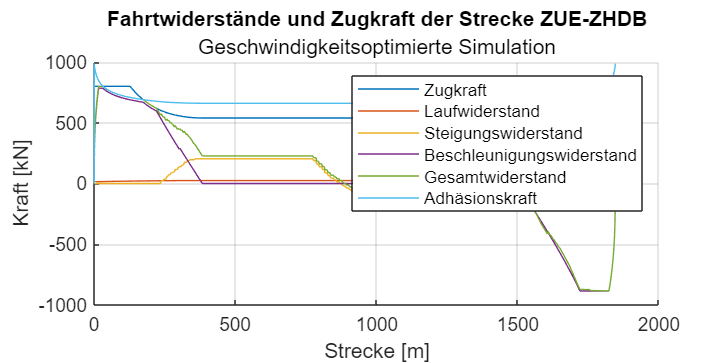

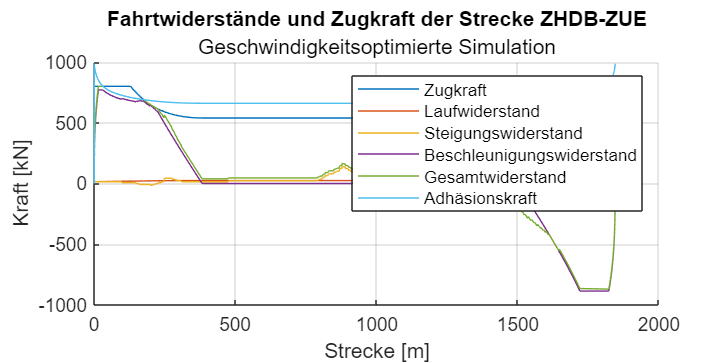

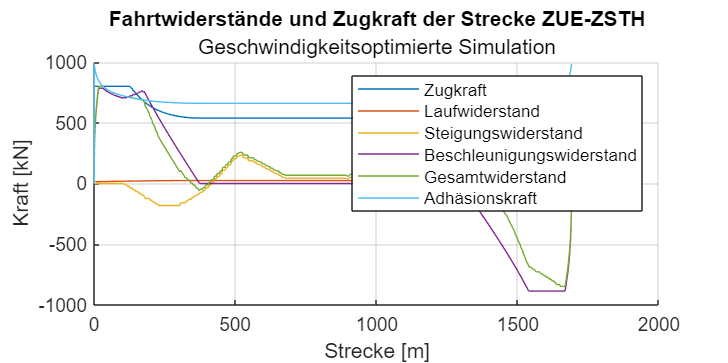

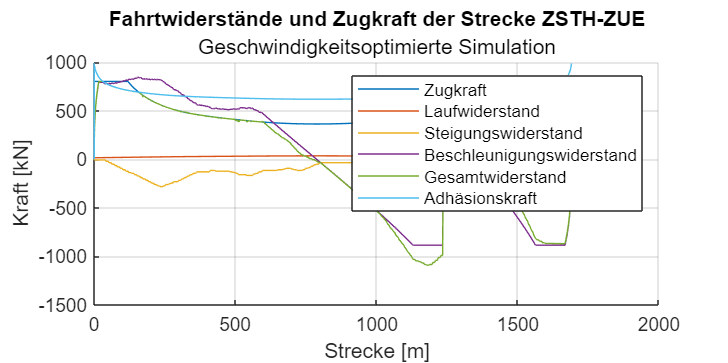

fnStr = fieldnames(SimStreckenU);

for n = 1:numel(fnStr)
    figure
    set(gcf, 'Units', 'centimeters','Position', [0,0,20,10])
    hold on
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Zugkraft)
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Laufwiderstand)
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Steigungswiderstand)
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Beschleunigungswiderstand)
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).Gesamtwiderstand)
    plot(SimStreckenU.(fnStr{n}).Strecke, SimStreckenU.(fnStr{n}).('Adhäsionskraft'))
    hold off
    title('Fahrtwiderstände und Zugkraft der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')))
    %subtitle('Fahrtzeit: ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
    subtitle('Geschwindigkeitsoptimierte Simulation')
    ylabel('Kraft [kN]')
    xlabel('Strecke [m]')
    legend('Zugkraft', 'Laufwiderstand', 'Steigungswiderstand', 'Beschleunigungswiderstand', 'Gesamtwiderstand', 'Adhäsionskraft', 'Location', 'northeast')
    grid()
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\', savename +'.png');
    exportgraphics(gcf, filename, 'Resolution',300)
    
end

## 1.7.) Fahrtwiderstände während der Simulation (X-Achse: Fahrtzeit) 

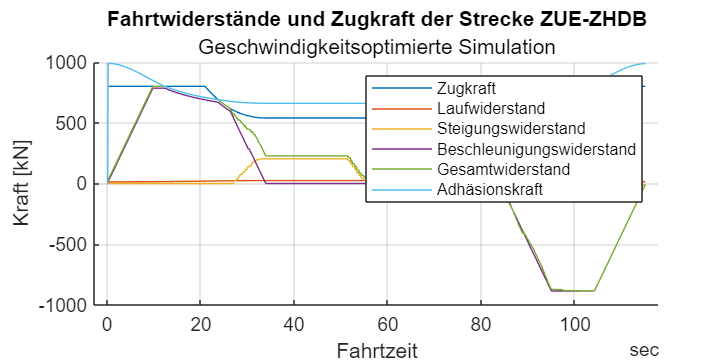

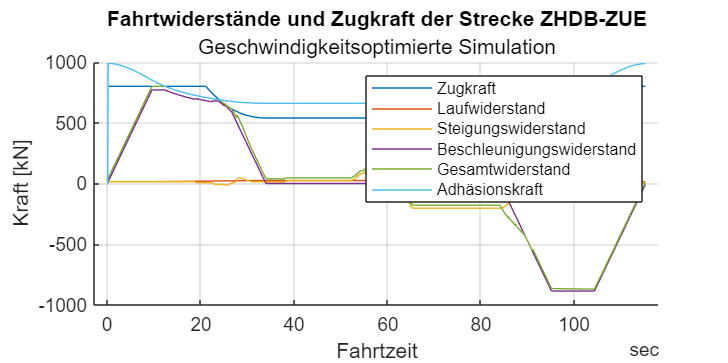

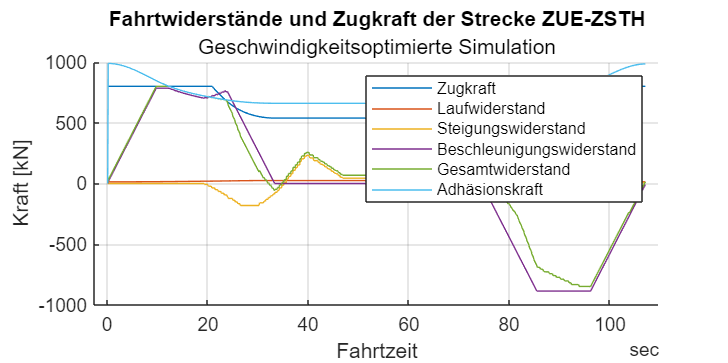

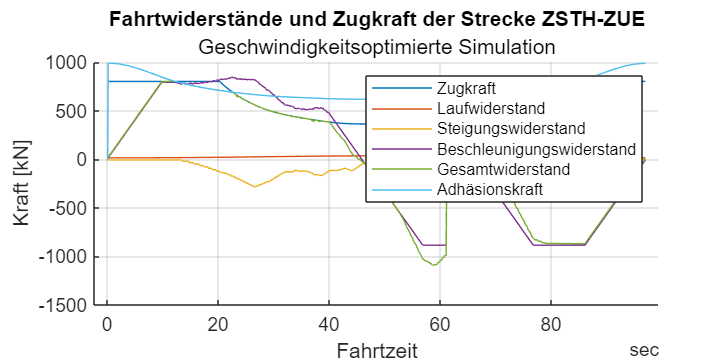

fnStr = fieldnames(SimStreckenU);

for n = 1:numel(fnStr)
    figure
    set(gcf, 'Units', 'centimeters','Position', [0,0,20,10])
    hold on
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Zugkraft)
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Laufwiderstand)
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Steigungswiderstand)
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Beschleunigungswiderstand)
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).Gesamtwiderstand)
    plot(SimStreckenU.(fnStr{n}).time, SimStreckenU.(fnStr{n}).('Adhäsionskraft'))
    hold off
    title('Fahrtwiderstände und Zugkraft der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')))
    %subtitle('Fahrtzeit: ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
    subtitle('Geschwindigkeitsoptimierte Simulation')
    ylabel('Kraft [kN]')
    xlabel('Fahrtzeit')
    legend('Zugkraft', 'Laufwiderstand', 'Steigungswiderstand', 'Beschleunigungswiderstand', 'Gesamtwiderstand', 'Adhäsionskraft', 'Location', 'northeast', 'FontSize', 8)
    grid()
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\', savename +'.png');
    exportgraphics(gcf, filename, 'Resolution',300)
    
end

## 1.8.) Z-V Diagramm während der Zugfahrt

v = 0:0.1:120;
F_max = 800; 
v_transit = 54;
P_max = 12000;
F = zeros(1,length(v));
mu = zeros(1,length(v));
F_wheel = zeros(1,length(v));
G_T = FZ.M_axle * FZ.N_axles * const.g;

for n = 1:length(v)
    mu(n) = 7.5/(v(n) + 44) + 0.161; % (-)
    F_wheel(n) = mu(n) * G_T; % (kN)
    if(v(n) < 54)
        F(n) = F_max;
    else
        F(n) = P_max/(v(n)/3.6);
    end
end
figure
set(gcf, 'Units', 'centimeters','Position', [1,1,18,10])
hold on
plot(v,F)
plot(v,F_wheel)
plot(v_transit,F_max, 'r*')
title('Z-V Diagramm für den Fahrzeugtyp KISS in zweifacher Komposition')
grid()
ylim([0,1000])
legend('Zugkraft', 'Adhäsionskraft')
ylabel('Kraft [kN]')
xlabel('Geschwindigkeit [km/h]')
annotation('textbox', [0.45, 0.81, 0.1, 0.1], 'String', "Transitionspunkt", "LineStyle","none", "FontSize",10)
annotation('arrow', [.51 .478], [.84 .76])
hold off
% speichern der plots
savename = "Z_V_Diagramm_KISS_Zweifachkomposition";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\RE450\Z_V_Diagramme\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

for n = 1:numel(fnStr)
    figure
    set(gcf, 'Units', 'centimeters','Position', [1,1,16,8])
    hold on
    plot(SimStreckenU.(fnStr{n}).Geschwindigkeit, SimStreckenU.(fnStr{n}).Zugkraft)
    plot(SimStreckenU.(fnStr{n}).Geschwindigkeit, SimStreckenU.(fnStr{n}).('Adhäsionskraft'))
    hold off
    grid()
end

## 2.) Gesamtleistung über den gesamten simulierten Fahrplan

time = seconds(0:0.1:86399.9)'; 
time.Format = 'hh:mm:ss.S';
figure
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
plot(time, P_totSim/1000)
xtickformat('hh:mm')
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
title('Simulierte Gesamtleistung im Speisepunkt Museumstrasse')
subtitle('Fahrzeug: KISS in einfacher Komposition mit Fahrplanoptimierter Simulation')
grid()

% speichern der plots
Speicherort =  "Fahrplanoptimierte_Simulation"; %"Geschwindigkeitsoptimierte_Simulation"
Fahrzeug = "RE450";
savename = "Gesamtleistung_Fahrplan";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)


## 2.1.) Gesamtleistung über den gesamten simulierten Fahrplan mit Zoom

time = seconds(0:0.1:86399.9)'; 
time.Format = 'hh:mm:ss.S';
figure
tiledlayout(2,1);
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
plot(time, P_totSim/1000)
xtickformat('hh:mm')
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
title('Simulierte Gesamtleistung im Speisepunkt Museumstrasse')
subtitle('Fahrzeug: KISS in zweifacher Komposition mit geschwindigkeitsopt. Sim.')
grid()

nexttile
plot(time(215000:225000), P_totSim(215000:225000)/1000)
%plot(time(285000:295000), P_totSim(285000:295000)/1000)
xtickformat('hh:mm')
%xticks(time(285000):minutes(5):time(295000))
xticks(time(215000):minutes(5):time(225000))
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
grid()

% speichern der plots
savename = "Gesamtleistung_Fahrplan_Zoomed";
%filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\', savename +'.png');
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Strecken_FahrplanSimulation\' + Fahrzeug + '\' + Speicherort + '\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)


## 2.2.) Messdaten

figure
tiledlayout(2,1);
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])
  
hold on
nexttile
plot(Meas.DatumZeit, Meas.P8minMittelMW)
ylabel('Leistung [MW]')
grid()
title('Leistung und Strom gemessen am Speisepunkt Zürich Museumstrasse')
subtitle('Messwerte über 8 min gemittelt')

nexttile
plot(Meas.DatumZeit, Meas.I8minMittelA)
ylabel('Strom [A]')
grid()
hold off
xlabel('Datum')

% speichern der plots
savename = "Leistung_Strom_Speisepunkt_Museumstrasse";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Messwerte_Speisepunkt_Museumstrasse\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)



## 2.3.) Fahrplansimulation und vergleich mit Messwerten

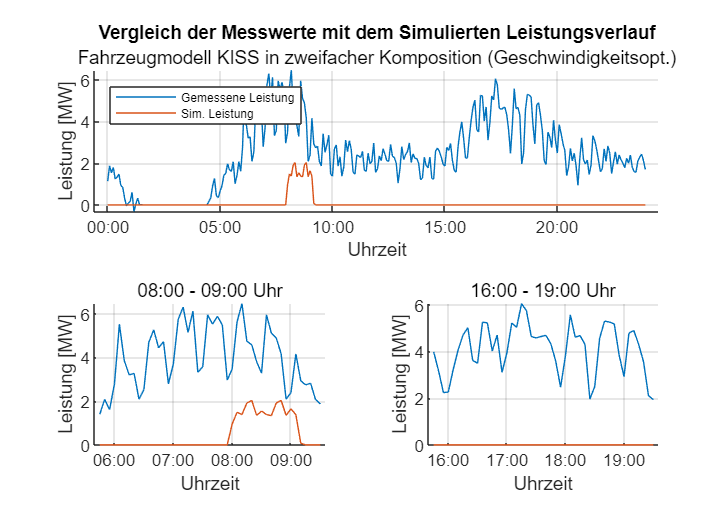

P_totSimMean = zeros(288,1);

n = 1;
for i = 1:3000:864000
    if (i < 4800)
        P_totSimMean(n,1) = mean(P_totSim(1:i));
    else
        P_totSimMean(n,1) = mean(P_totSim(i-4800:i));
    end
    n = n + 1;
end

% Erstellung eines Zeitarrays für die 5 min. Mittelwerte (alle 5 Min.)
time2 = seconds(0:300:86400-300);
time2.Format = 'hh:mm:ss.S';
leg = [];

figure
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])
tiledlayout(2,2)


nexttile([1 2])
%nexttile
hold on
% Montag:
plot(time2, Meas.P8minMittelMW(1:length(time2)))
% Sonntag:
%plot(time2, Meas.P8minMittelMW(1729:2016))

leg = ["Gemessene Leistung", "Sim. Leistung"];
plot(time2, P_totSimMean/1000)
title('Vergleich der Messwerte mit dem Simulierten Leistungsverlauf')
subtitle('Fahrzeugmodell KISS in zweifacher Komposition (Geschwindigkeitsopt.)')
grid()
legend(leg, 'Location', 'northwest', 'FontSize', 6)
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
xtickformat('hh:mm')
hold off

nexttile
hold on
% Montag:
plot(time2(70:115), Meas.P8minMittelMW(70:115))
% Sonntag:
%plot(time2(70:115), Meas.P8minMittelMW(1798:1843))
leg = ["Gemessene Leistung", "Sim. Leistung"];
plot(time2(70:115), P_totSimMean(70:115)/1000)
subtitle('08:00 - 09:00 Uhr')
grid()
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
xtickformat('hh:mm')
hold off

nexttile
hold on
% Montag:
plot(time2(190:235), Meas.P8minMittelMW((190:235)))
% Sonntag:
%plot(time2(1918:1953), Meas.P8minMittelMW((1918:1953)))
leg = ["Gemessene Leistung", "Sim. Leistung"];
plot(time2(190:235), P_totSimMean(190:235)/1000)
subtitle('16:00 - 19:00 Uhr')
grid()
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
xtickformat('hh:mm')
hold off

% 
% % speichern der plots
% savename = "Vergleich_Messwerte_Simulation_KISS_Zweifach_SpeedOpt2";
% filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Messwerte_Speisepunkt_Museumstrasse\', savename +'.png');
% exportgraphics(gcf, filename, 'Resolution',300)

